## Study of a system coupled to an harmonic bath

We study systems of the form $H=\frac{p^2 }{2m}+V\left(X\right)+\sum_{\alpha } \frac{p_{\alpha }^2 }{2m}+\frac{1}{2}m_{\alpha } {\omega_{\alpha } }^2 x_{\alpha }^2 -{\mathrm{xc}}_{\alpha } x_{\alpha }$, where greec subscripts denote bath variables. 

For such Hamiltonian, the imaginary time correlation function is given by (see Feynman Vernon) :


$$C^i \left(\tau \right)=\frac{1}{Z}\int_{x\left(0\right)=x\left(\beta \right)} \mathrm{Dx}\left(z\right)\;x\left(0\right)x\left(\tau \right)I\left\lbrack x\right\rbrack e^{-H\left\lbrack X\right\rbrack }$$



$$I\left\lbrack x\right\rbrack =\mathrm{exp}\left\lbrace -\int_z \mathrm{dz}\int_{\mathrm{z'}<z} \mathrm{dz'}\;x\left(z\right)L\left(z-\mathrm{z'}\right)x\left(\mathrm{z'}\right)\right\rbrace$$



$$L\left(z-\mathrm{z'}\right)=\frac{1}{\pi }\int_0^{\infty } d\omega \;J\left(\omega \right)\frac{\mathrm{cosh}\left(\frac{\beta \omega }{2}+\omega \left(z-\mathrm{z'}\right)\right)}{\mathrm{sinh}\left(\frac{\beta \omega }{2}\right)}$$


We will model a fluid of Lennard-Jones particles, where :

$J\left(\omega \right)=\frac{\pi }{2}\sum_{\alpha } \frac{{c^2 }_{\alpha } }{m_{\alpha } \omega_{\alpha } }\delta \left(\omega -\omega_{\alpha } \right)=\omega \int_0^{\infty } \mathrm{dt}\;\mathrm{cos}\left(\omega t\right)\xi \left(t\right)$, where


$$\xi \left(t\right)=\xi_0 \left\lbrace e^{-\alpha_1 {\left(\mathrm{ft}\right)}^2 } \left\lbrack 1+a_1 {\left(\mathrm{ft}\right)}^4 \right\rbrack +a_2 {\left(\mathrm{ft}\right)}^4 e^{-\alpha_2 {\left(\mathrm{ft}\right)}^2 } \right\rbrace$$


with $\xi_0 =225,a_1 =1\ldotp 486\times {10}^5 ,a_2 =285,\alpha_1 =903,\;\alpha_2 =75\;\mathrm{and}\;f=0\ldotp 2$

## Friction Kernel

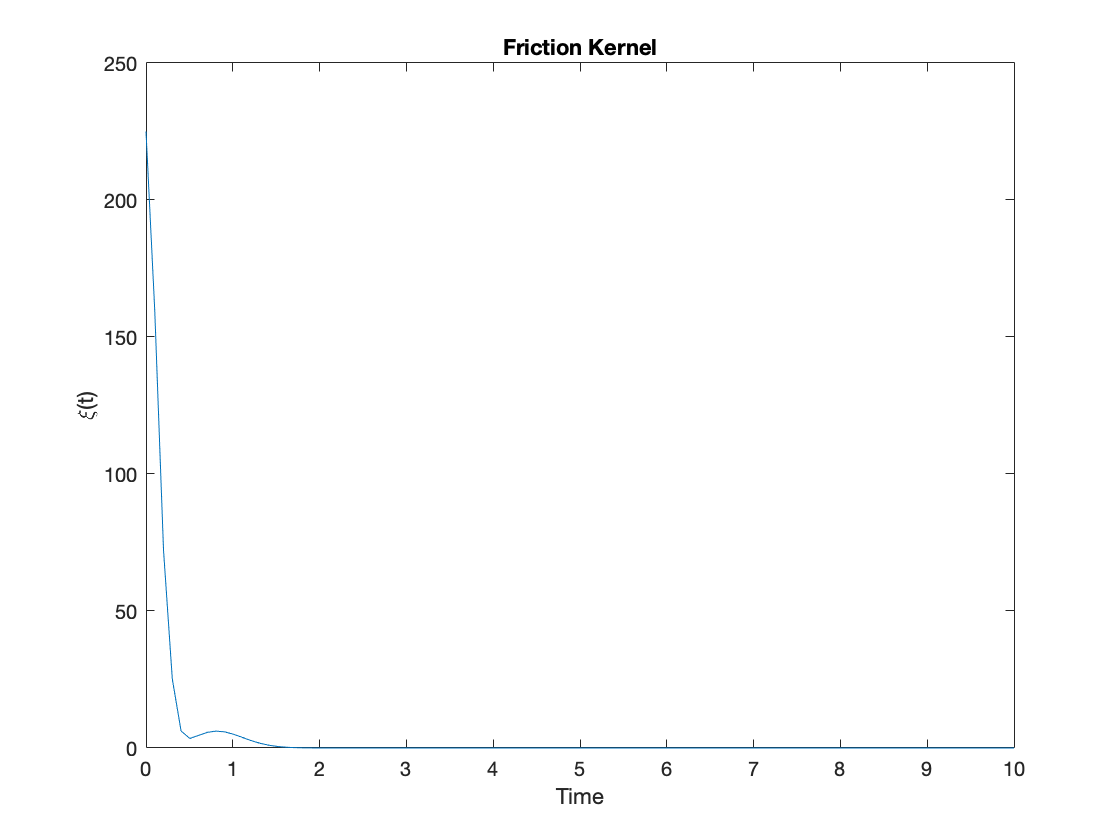

% Parameters
xi_0=225;
a1=1.486*10^5;
a2=285;
alpha1=903;
alpha2=75;
f=0.2;
% Formula
xi = @(t) xi_0*( exp(-alpha1*(f*t).^2).*(1+a1*(f*t).^4) + a2*(f*t).^4.*exp(-alpha2*(f*t).^2));
% Plot
t=linspace(0,10,100);
plot(t,xi(t))
title("Friction Kernel")
xlabel("Time")
ylabel("\xi(t)")

The integral for finding $J\left(\omega \right)$can safely be cut at $t=10$.

## Environment Spectral density Function

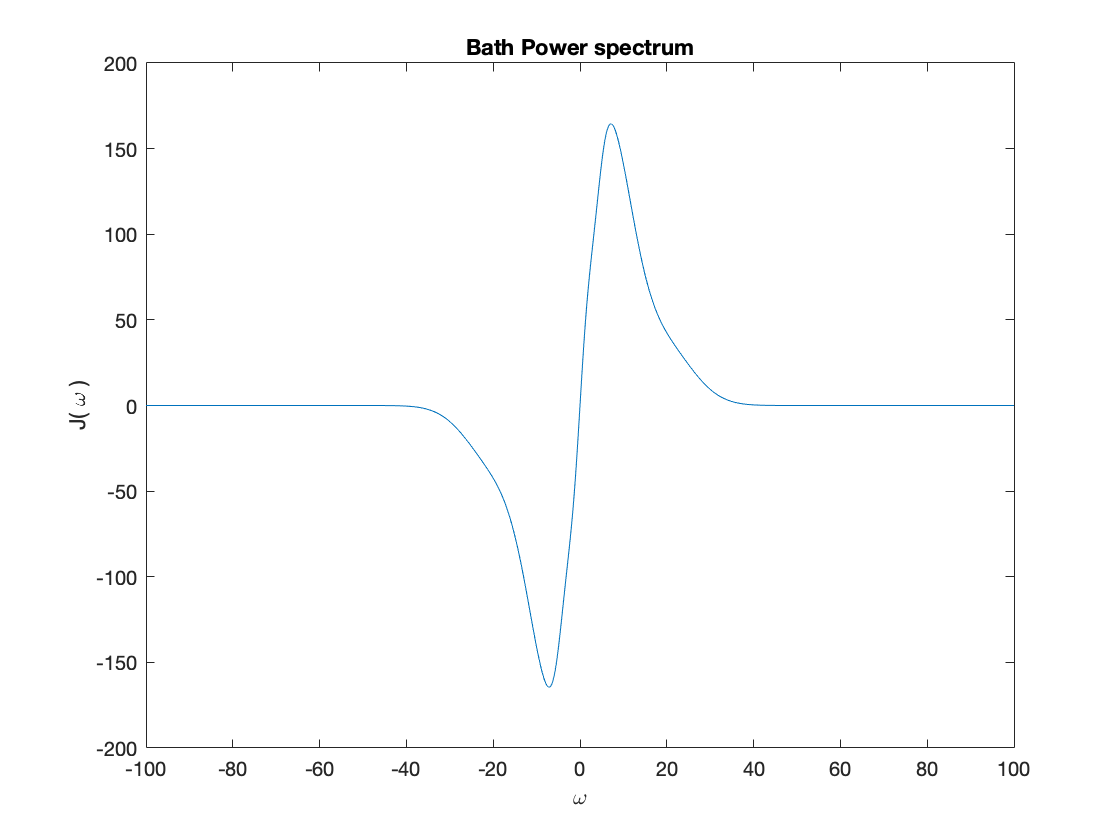

integrand=@(t,omega) cos(omega.*t).*xi(t);
J = @(omega) omega.*integral(@(x)integrand(x,omega),0,10,'ArrayValued',true);

omega=linspace(-100,100,2000)';
plot(omega,J(omega))
title("Bath Power spectrum")
xlabel("\omega")
ylabel("J( \omega )")

So once again, $J\left(\omega \right)$ can be truncated, for e.g at $\omega =75$

## L(Z)

We now compute the force autocorrelation function of the environment $L\left(z-\mathrm{z'}\right)=\frac{1}{\pi }\int_0^{\infty } d\omega \;J\left(\omega \right)\frac{\mathrm{cosh}\left(\frac{\beta \omega }{2}+\omega \left(z-\mathrm{z'}\right)\right)}{\mathrm{sinh}\left(\frac{\beta \omega }{2}\right)}$

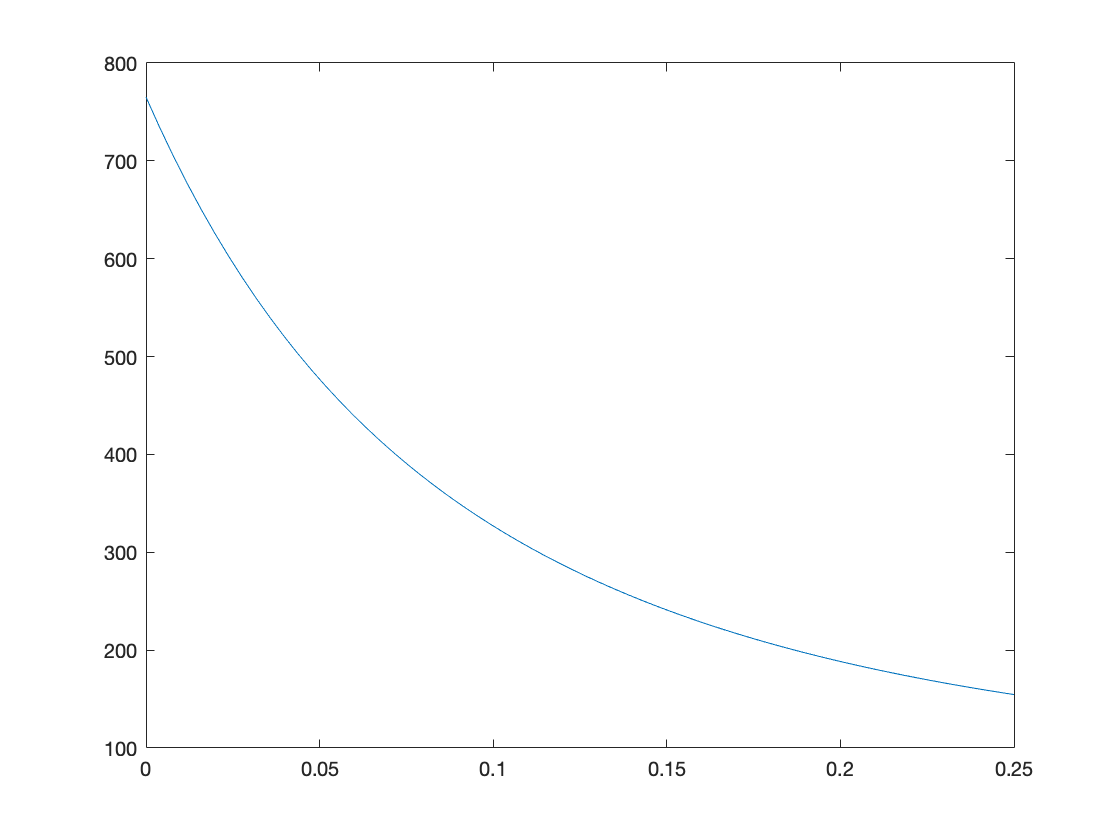


N=64;
tau = linspace(0,0.25,N);
i=0:(N-1);

L=@(n) 1/pi*integral(@(w)J(w).*cosh(w/2-1*w.*n*(tau(2)-tau(1)))./sinh(0.5*w),0,80,'ArrayValued',true );


figure
plot(tau,abs(L(i')))

## Power spectrum

If the previous described system describes a bath to which we couple an harmonic oscillator, we can compute its power spectrum.

## "Self Enegy"


M=1;
omega_=10;


## A Imaginary Part

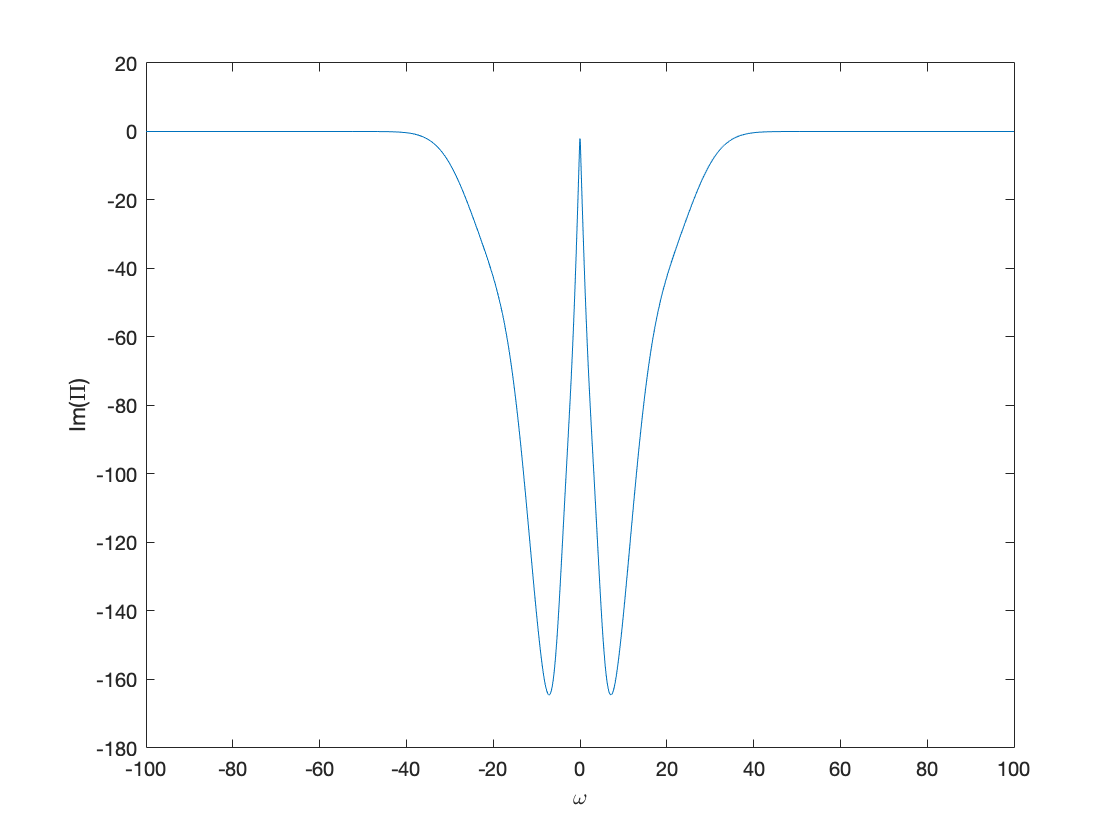


IM_PI =@(O) -sign(O).*J(O)/M;
plot(omega,IM_PI(omega))
xlabel('\omega')
ylabel('Im(\Pi)')

## B Real Part

RE_PI = @(O) -1/pi*integral(@(o_p) 1./(O-o_p).*IM_PI(o_p),-100,100,'ArrayValued',true);




## Ohmic dissipation

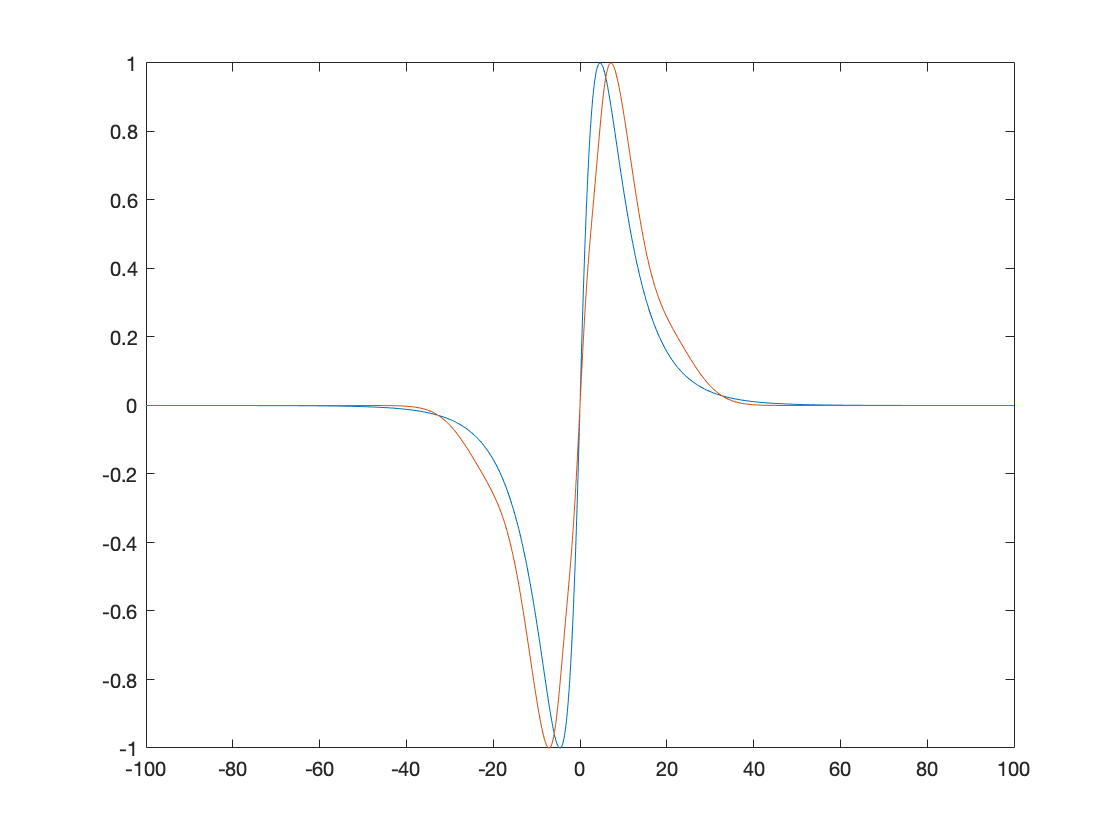

hold off

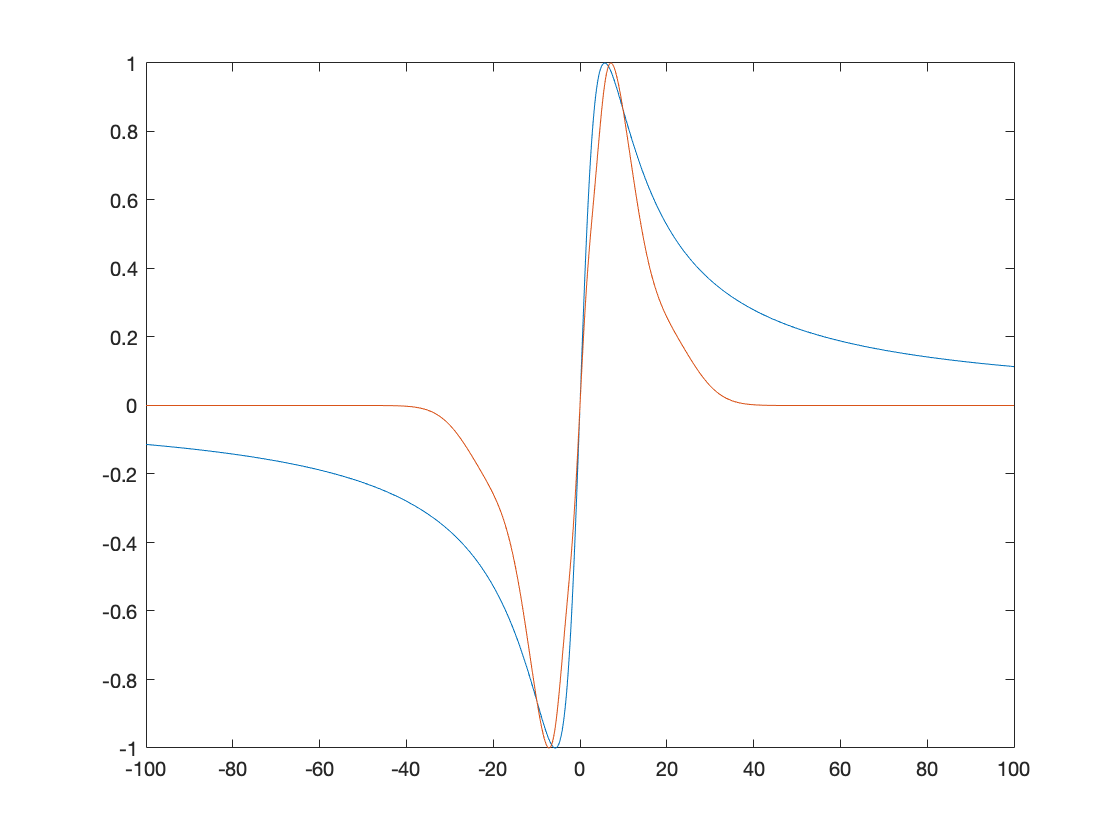

plot(omega,omega./(1+omega.^2/5.7^2)/max(omega./(1+omega.^2/5.7^2)))
hold on
plot(omega,J(omega)/max(J(omega)))

## Non-Ohmic dissipation

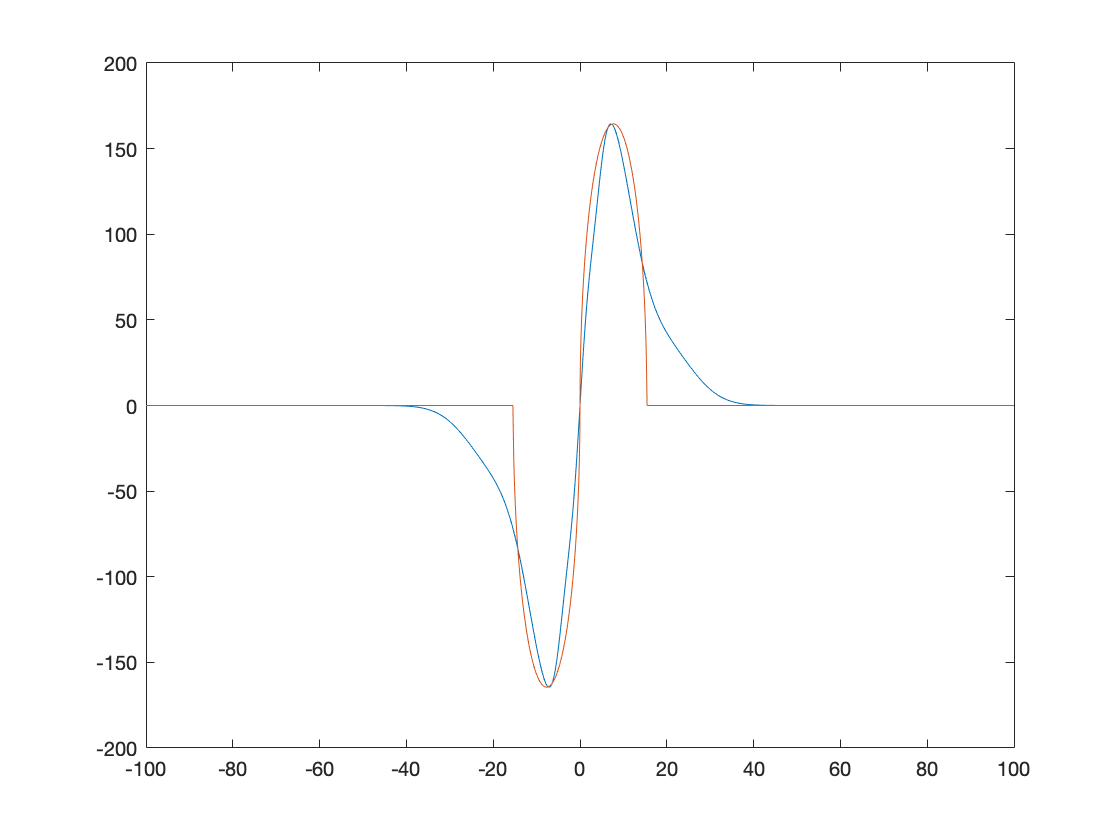

w_b = 7.7;
w_d = 7.7;
im_se = zeros(length(omega),1);
index = find(w_d>abs(omega-w_b));
im_se(index)=sqrt(w_d^2 - (omega(index)-w_b).^2);
index=find(w_d>abs(omega+w_b));
im_se(index)=-sqrt(w_d^2 - (omega(index)+w_b).^2);
im_se=im_se/max(im_se)*max(J(omega));
plot(omega,J(omega))
hold on
plot(omega,im_se)
hold off

## Self Energy And Friction Kernel

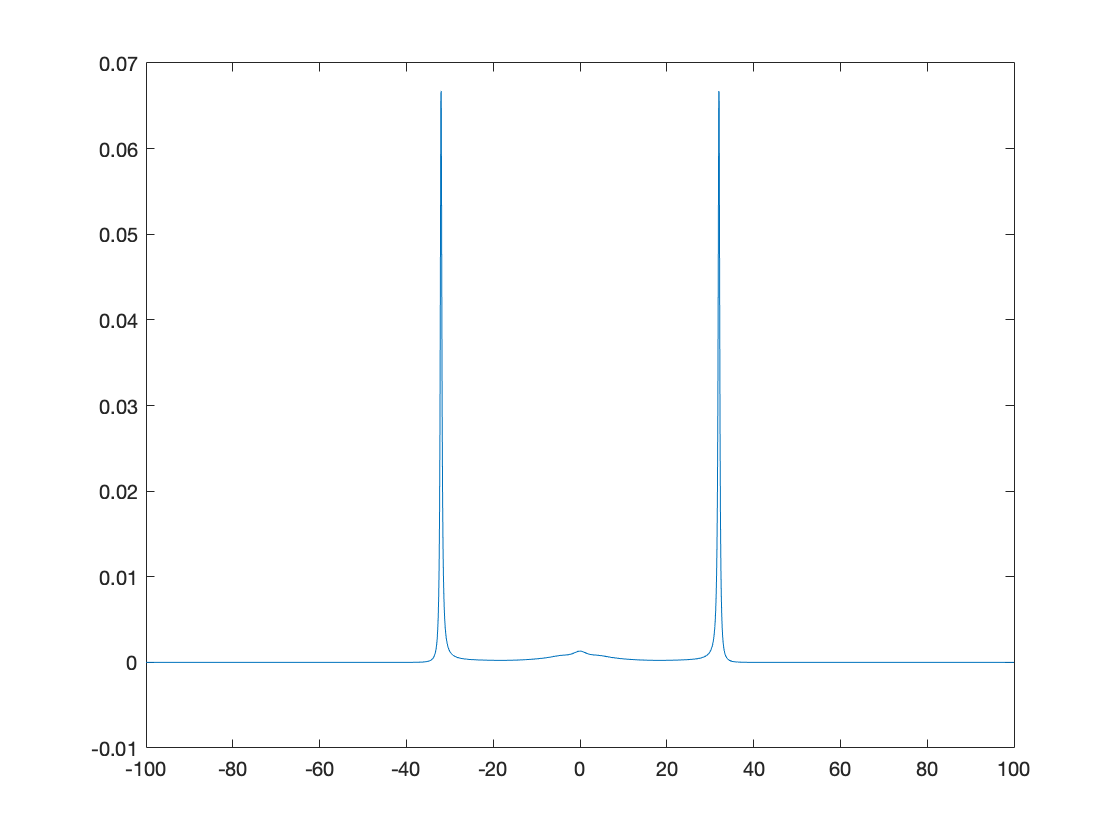

M=0.4;
im_se = -J(omega)/M;
integrand_bis=@(t,omega) sin(omega.*t).*xi(t)/M;
re_se = @(omega) omega.*integral(@(x)integrand_bis(x,omega),0,10,'ArrayValued',true);

omega_0=20;
spectrum = -coth(omega/2).*im_se./((omega.^2-omega_0.^2-re_se(omega)).^2+(im_se).^2);
close all;
plot(omega,spectrum)
hold off

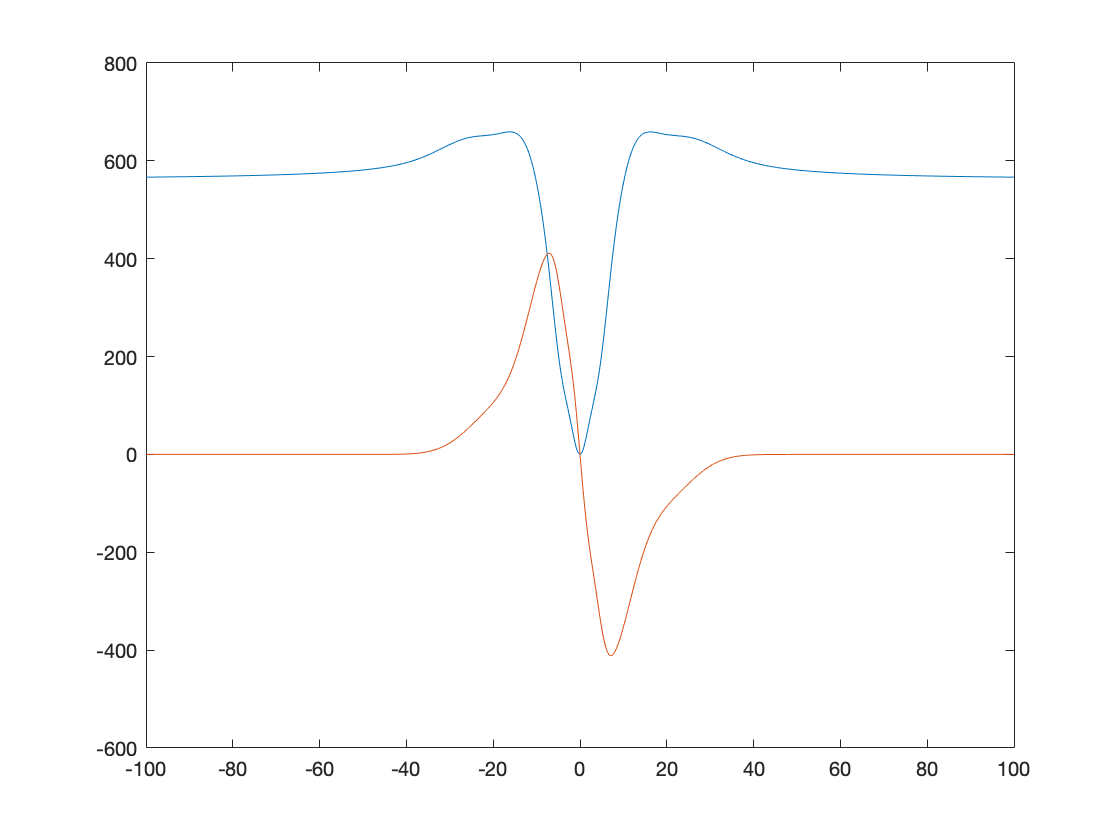

plot(omega,re_se(omega))
hold on
plot(omega,im_se)